Creating the Inputs, Targets, and Validations Matrices from Imported data

% Reading data matrix from the folder. Total samples is 187.
data = readmatrix("data.xlsx"); 

% Useful variables for the code
n = height(data);
w = width(data);
k = round(0.2*n,0);
t = n-k;

% Preallocation for efficiency. 
training = zeros(t,w);
testing = zeros(k,w);
random_data = zeros(n,w);

% Creating matrix of random indexes
indexes = randsample(n,n); 

% Reorganizing the data matrix rows based on created random indexes
for i = 1:n
    random_data(i,:) = data(indexes(i),:);
end

% Creating a random subset of testing data
for i = 1:k
    testing(i,:) = random_data(i,:);
end

% Creating a random set of training data
for i = 1:t
    training(i,:) = random_data(i+k,:);
end

% Preallocating for efficiency
inputs = zeros(t,4);
targets = zeros(t,3);
testinputs = zeros(k,4);
testtargets = zeros(k,3);


% Populating the inputs and target matrices
for i = 1:t
    inputs(i,1:4) = training(i,5:8);
    targets(i,1:3) = training(i,2:4);
end

% Populating the test sets 
 for i = 1:k
     testinputs(i,1:4) = testing(i,5:8);
     testtargets(i,1:3) = testing(i,2:4);
 end

**Visualization of data - Delete the log part of the code in section 1 (loops populating targets) to see the correct histograms**

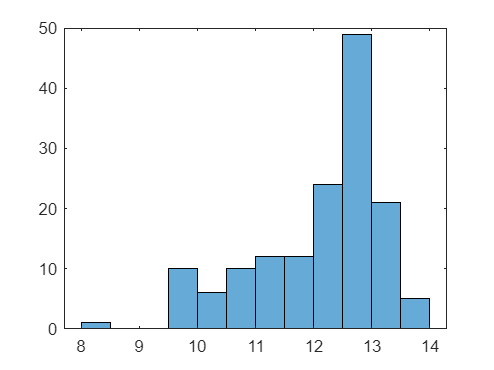

histogram(targets(:,1)); 

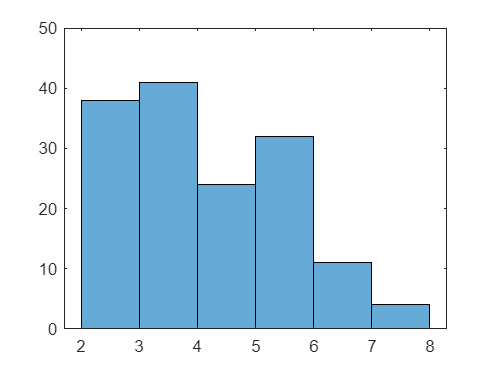

histogram(targets(:,2));

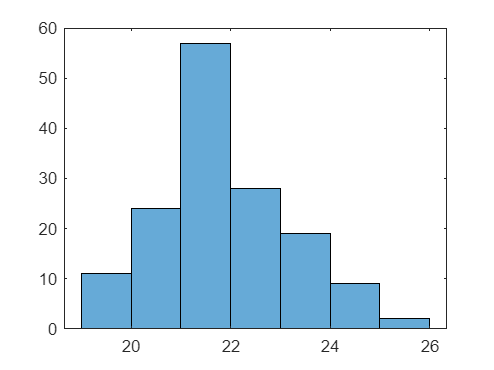

histogram(targets(:,3));

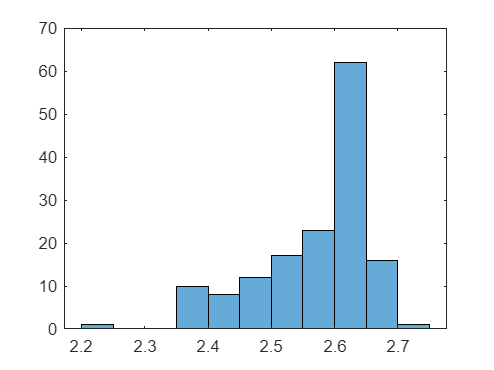


histogram(log(targets(:,1)+1)');

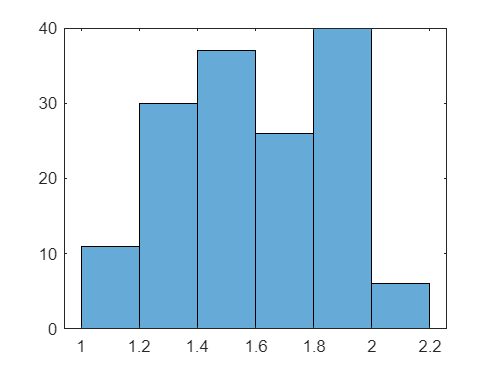

histogram(log(targets(:,2)+1)');

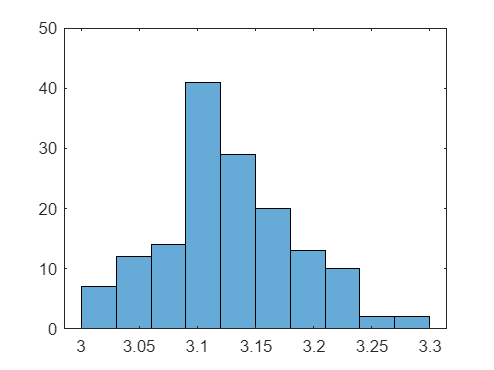

histogram(log(targets(:,3)+1)');

**Plotting Input Data To Visualize their Relationship to the Targets**

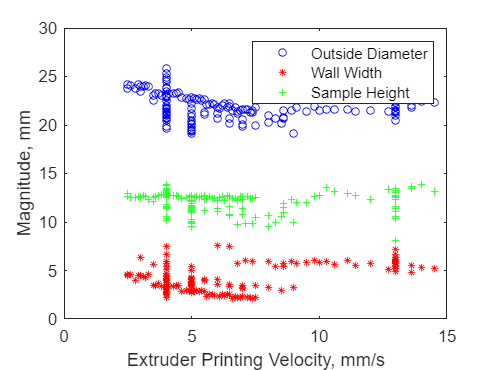

       % Checking Relationship between Velocity and Targets
plot(inputs(:,1), targets(:,3),'b o','MarkerSize',4.5);
hold on
plot(inputs(:,1), targets(:,2),'r *','MarkerSize',4.5);
plot(inputs(:,1), targets(:,1),'g +','MarkerSize',4.5);
hold off
xlabel('Extruder Printing Velocity, mm/s');
ylabel('Magnitude, mm');
legend({'Outside Diameter','Wall Width', 'Sample Height'},'Location','northeast','Orientation','vertical');
xlim([0 15]);
ylim([0 30]);

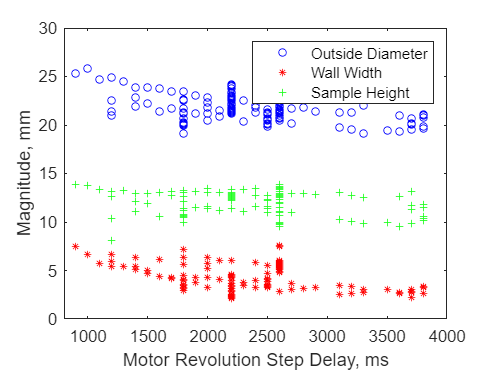


    % Checking Relationship between Delay and Targets
plot(inputs(:,2), targets(:,3),'b o','MarkerSize',4.5);
hold on
plot(inputs(:,2), targets(:,2),'r *','MarkerSize',4.5);
plot(inputs(:,2), targets(:,1),'g +','MarkerSize',4.5);
hold off
xlabel('Motor Revolution Step Delay, ms');
ylabel('Magnitude, mm');
legend({'Outside Diameter','Wall Width', 'Sample Height'},'Location','northeast','Orientation','vertical')
xlim([800 4000]);
ylim([0 30]);

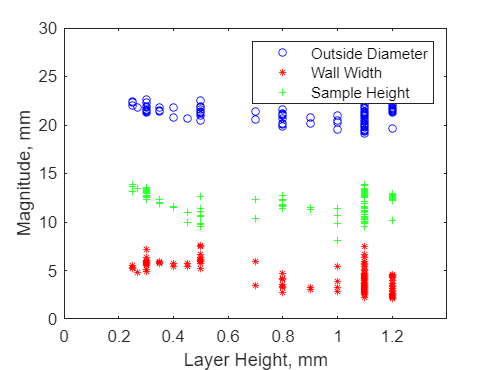


    % Checking Relationship between Layer Height and Targets
plot(inputs(:,3), targets(:,3),'b o','MarkerSize',4.5);
hold on
plot(inputs(:,3), targets(:,2),'r *','MarkerSize',4.5);
plot(inputs(:,3), targets(:,1),'g +','MarkerSize',4.5);
hold off
xlabel('Layer Height, mm');
ylabel('Magnitude, mm');
legend({'Outside Diameter','Wall Width', 'Sample Height'},'Location','northeast','Orientation','vertical')
xlim([0 1.4]);
ylim([0 30]);

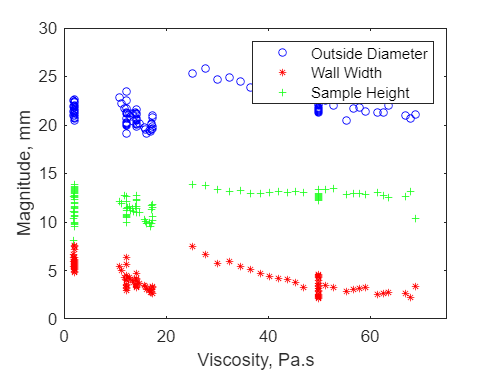


   % Checking Relationship between Viscosity and Targets
plot(inputs(:,4), targets(:,3),'b o','MarkerSize',4.5);
hold on
plot(inputs(:,4), targets(:,2),'r *','MarkerSize',4.5);
plot(inputs(:,4), targets(:,1),'g +','MarkerSize',4.5);
hold off
xlabel('Viscosity, Pa.s');
ylabel('Magnitude, mm');
legend({'Outside Diameter','Wall Width', 'Sample Height'},'Location','northeast','Orientation','vertical')
xlim([0 75]);
ylim([0 30]);

**Normalizing Inputs and Test Inputs sets. Targets were not normalized**

% Prellocating for efficiency. Matrix X contains all inputs. Matrix Xtest
% contains all test set inputs
x = zeros(t,4);
xtest = zeros(k,4);

% This loop populates the matrix containing the normalized inputs
for i = 1:t    
    x(i,1) = (inputs(i,1)-min(inputs(:,1)))/(max(inputs(:,1)) - min(inputs(:,1)));
    x(i,2) = (inputs(i,2)-min(inputs(:,2)))/(max(inputs(:,2)) - min(inputs(:,2)));    
    x(i,3) = (inputs(i,3)-min(inputs(:,3)))/(max(inputs(:,3)) - min(inputs(:,3)));
    x(i,4) = (inputs(i,4)-min(inputs(:,4)))/(max(inputs(:,4)) - min(inputs(:,4)));
end


% This loop populates the matrix containing the normalized test matrix inputs
for i = 1:k
    xtest(i,1) = (testinputs(i,1)-min(testinputs(:,1)))/(max(testinputs(:,1)) - min(testinputs(:,1)));
    xtest(i,2) = (testinputs(i,2)-min(testinputs(:,2)))/(max(testinputs(:,2)) - min(testinputs(:,2)));
    xtest(i,3) = (testinputs(i,3)-min(testinputs(:,3)))/(max(testinputs(:,3)) - min(testinputs(:,3)));
    xtest(i,4) = (testinputs(i,4)-min(testinputs(:,4)))/(max(testinputs(:,4)) - min(testinputs(:,4)));
end

**Plotting Inputs after normalizing to check if data looks correct**

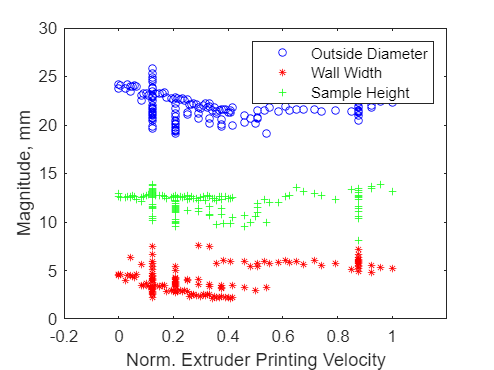

     % Checking Velocity Normalization
plot(x(:,1), targets(:,3),'b o','MarkerSize',4.5,'DisplayName','Outside Diameter');
hold on
plot(x(:,1), targets(:,2),'r *','MarkerSize',4.5);
plot(x(:,1), targets(:,1),'g +','MarkerSize',4.5);
hold off
xlabel('Norm. Extruder Printing Velocity');
ylabel('Magnitude, mm');
legend({'Outside Diameter','Wall Width', 'Sample Height'},'Location','northeast','Orientation','vertical');
xlim([-0.2 1.2]);
ylim([0 30]);

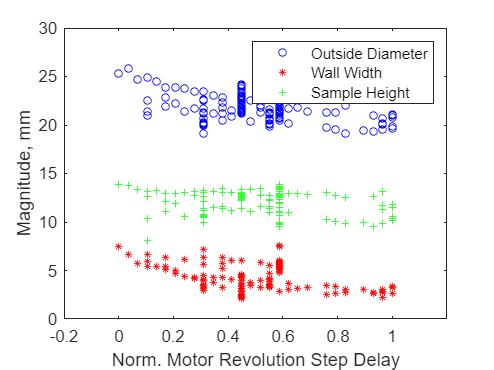


    % Checking Delay Normalization
plot(x(:,2), targets(:,3),'b o','MarkerSize',4.5,'DisplayName','Outside Diameter');
hold on
plot(x(:,2), targets(:,2),'r *','MarkerSize',4.5);
plot(x(:,2), targets(:,1),'g +','MarkerSize',4.5);
hold off
xlabel('Norm. Motor Revolution Step Delay');
ylabel('Magnitude, mm');
legend({'Outside Diameter','Wall Width', 'Sample Height'},'Location','northeast','Orientation','vertical')
xlim([-0.2 1.2]);
ylim([0 30]);

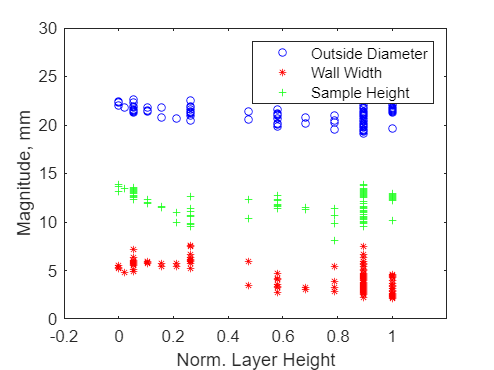


    % Checking Layer Height Normalization
plot(x(:,3), targets(:,3),'b o','MarkerSize',4.5,'DisplayName','Outside Diameter');
hold on
plot(x(:,3), targets(:,2),'r *','MarkerSize',4.5);
plot(x(:,3), targets(:,1),'g +','MarkerSize',4.5);
hold off
xlabel('Norm. Layer Height');
ylabel('Magnitude, mm');
legend({'Outside Diameter','Wall Width', 'Sample Height'},'Location','northeast','Orientation','vertical')
xlim([-0.2 1.2]);
ylim([0 30]);

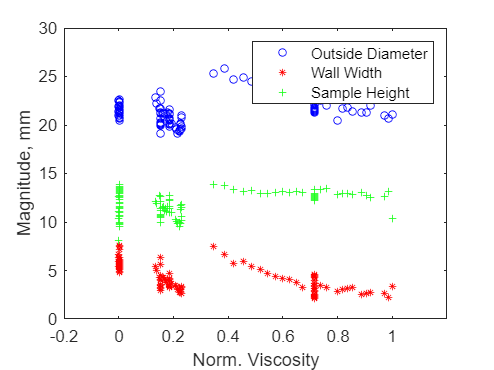


% Checking Viscosity Normalization
plot(x(:,4), targets(:,3),'b o','MarkerSize',4.5);
hold on
plot(x(:,4), targets(:,2),'r *','MarkerSize',4.5);
plot(x(:,4), targets(:,1),'g +','MarkerSize',4.5);
hold off
xlabel('Norm. Viscosity');
ylabel('Magnitude, mm');
legend({'Outside Diameter','Wall Width', 'Sample Height'},'Location','northeast','Orientation','vertical')
xlim([-0.2 1.2]);
ylim([0 30]);

**Defining Input Matrix and Target Matrix for Training**

% Populating the target matrices with transformed values (ln) for
% dimensions wall width and OD
for i = 1:t
    targets(i,1) = log(targets(i,1)+1);
    targets(i,2) = log(targets(i,2)+1); 
    targets(i,3) = log(targets(i,3)+1);
end

% Populating the testing target matrix set with log values
 for i = 1:k
     testtargets(i,1) = log(testtargets(i,1)+1);
     testtargets(i,2) = log(testtargets(i,2)+1);
     testtargets(i,3) = log(testtargets(i,3)+1);
 end

% Transpose of inputs and targets to train the network. Matrix Y1t contains
% all the targets.
xt = x';
y1t = targets';

**Training of the NN - After RMSE Optimization Analysis **


% hidden_size defines the number of neurons and layers
hidden_size = [30,30];
net = feedforwardnet(hidden_size);

% Defining the Transfer Function at each layer
net.layers{1}.transferFcn = 'logsig'; % Can be either logsig, radbas, or purelin
net.layers{2}.transferFcn = 'logsig';% poslin

% Train Function definition
net.trainFcn = 'trainlm';
net.trainParam.epochs = 1000;

% Training and Validation Rations. Here the testing Ratio can also be
% defined but the testing matrix was created earlier already. Test must be
% defined as zero, otherwise the program will draw data to create it.
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 30/100;
net.divideParam.testRatio = 0/100;

% mean-squared error as the chosen loss function
net.performFcn = 'mse'; 

% Goal for the loss function
goal = 1e-6;
net.trainParam.goal = goal;

% Number of validation checks before training stops
valchecks = 30;
net.trainParam.max_fail = valchecks;

% Training of the NN. The matrix tr contains all the indexes of the data
% points that were chosen to train and validate
[net,tr] = train(net,xt,y1t);


**Performance Analysis - RMSE Values of Training and Validation Sets**

% Using NN's to make predictions y1pred using x data it was trained on.
% yactual stores the real values of y corresponding to the indexes of the
% training matrix.

ytrpred = net(xt(:,tr.trainInd));
yactual = y1t(:,tr.trainInd);
wtr = width(tr.trainInd);
for i = 1:wtr
    ytrpred(1,i) = exp(ytrpred(1,i))-1;
    ytrpred(2,i) = exp(ytrpred(2,i))-1;
    ytrpred(3,i) = exp(ytrpred(3,i))-1;
    yactual(1,i) = exp(yactual(1,i))-1;
    yactual(2,i) = exp(yactual(2,i))-1;
    yactual(3,i) = exp(yactual(3,i))-1;
end

% RMSE of the validation set of NN 
yvalpred = net(xt(:,tr.valInd));
yvalactual = y1t(:,tr.valInd);
wval = width(tr.valInd);
for i=1:wval
    yvalpred(1,i) = exp(yvalpred(1,i))-1;
    yvalpred(2,i) = exp(yvalpred(2,i))-1;
    yvalpred(3,i) = exp(yvalpred(3,i))-1;
    yvalactual(1,i) = exp(yvalactual(1,i))-1;
    yvalactual(2,i) = exp(yvalactual(2,i))-1;
    yvalactual(3,i) = exp(yvalactual(3,i))-1;
end

% RMSE of Training Set
error = ytrpred-yactual;
sq_error = (error) .^2;
sum_sq_error_h = sum(sq_error(1,:));
sum_sq_error_ww = sum(sq_error(2,:));
sum_sq_error_od = sum(sq_error(3,:));

fprintf('RSME of the Training Set:')

RSME of the Training Set:

tr_RMSE_h = sqrt(sum_sq_error_h/wtr)

tr_RMSE_h = 0.1643

tr_RMSE_ww = sqrt(sum_sq_error_ww/wtr)

tr_RMSE_ww = 0.1445

tr_RMSE_od = sqrt(sum_sq_error_od/wtr)

tr_RMSE_od = 0.2422


% RMSE of Validation Set
error = yvalpred-yvalactual;
sq_error = (error) .^2;
sum_sq_error_h = sum(sq_error(1,:));
sum_sq_error_ww = sum(sq_error(2,:));
sum_sq_error_od = sum(sq_error(3,:));

fprintf('RMSE of the Validation Set:')

RMSE of the Validation Set:

val_RMSE_h = sqrt(sum_sq_error_h/wval)

val_RMSE_h = 0.5378

val_RMSE_ww = sqrt(sum_sq_error_ww/wval)

val_RMSE_ww = 0.3254

val_RMSE_od = sqrt(sum_sq_error_od/wval)

val_RMSE_od = 0.3800

**Visualizing the predictions and the real values in a plot**

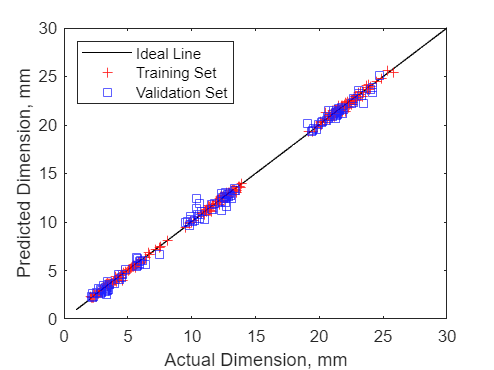

% Visualizing the error between training prediction and real values
yact = zeros(1,315);
ytr = zeros(1,315);
yvalx = zeros(1,135);
yvaly = zeros(1,135);
for i = 1:105
yact(1,i) = yactual(1,i);
yact(1,i+105) = yactual(2,i);
yact(1,i+210) = yactual(3,i);

ytr(1,i) = ytrpred(1,i);
ytr(1,i+105) = ytrpred(2,i);
ytr(1,i+210) = ytrpred(3,i);
end

for i = 1:45
yvalx(1,i) = yvalactual(1,i);
yvalx(1,i+45) = yvalactual(2,i);
yvalx(1,i+90) = yvalactual(3,i);

yvaly(1,i) = yvalpred(1,i);
yvaly(1,i+45) = yvalpred(2,i);
yvaly(1,i+90) = yvalpred(3,i);
end

plot(1:30, 1:30, 'k')
hold on
plot(yact, ytr, 'r +')
plot(yvalx, yvaly, 'b s')
hold off 
xlabel('Actual Dimension, mm')
ylabel('Predicted Dimension, mm')
legend({'Ideal Line','Training Set','Validation Set'},'Location','northwest','Orientation','vertical')



y1test = net(xtest');
for i=1:k
    y1test(1,i) = exp(y1test(1,i))-1;
    y1test(2,i) = exp(y1test(2,i))-1;
    y1test(3,i) = exp(y1test(3,i))-1;
    testtargets(i,1) = exp(testtargets(i,1))-1;
    testtargets(i,2) = exp(testtargets(i,2))-1;
    testtargets(i,3) = exp(testtargets(i,3))-1;
end

plot(1:k, y1test(1,:), 'r o'); hold on;
plot(1:k, y1test(2,:), 'b o');
plot(1:k, y1test(3,:), 'k o');
plot(1:k, testtargets(:,1), 'r *');
plot(1:k, testtargets(:,2), 'b *');
plot(1:k, testtargets(:,3), 'k *');hold off;
lgd = legend({'Sample Height','Wall Width', 'Outside Diameter'},'Location','northeast','Orientation','vertical')

lgd =   Legend (Sample Height, Wall Width, Outside Diameter) with properties:

         String: {'Sample Height'  'Wall Width'  'Outside Diameter'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6285 0.7741 0.2582 0.1262]
          Units: 'normalized'

  Show all properties


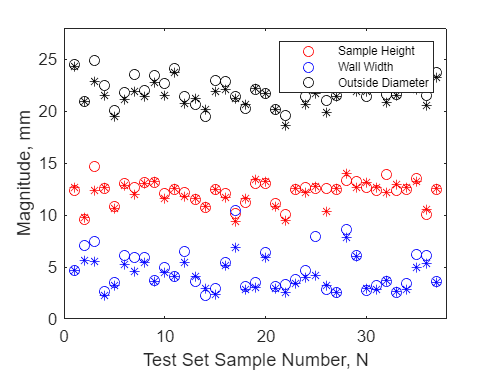

lgd.FontSize = 7;
xlim([0 38]);
ylim([0 28]);
xlabel('Test Set Sample Number, N');
ylabel('Magnitude, mm');hold off



tiledlayout(3,1);
    % Top plot
ax1 = nexttile

ax1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.7000 0.7750 0.2250]
            Units: 'normalized'

  Show all properties


plot(ax1,1:k, testtargets(:,1),'b o', 1:k, y1test(1,:), 'r *')
title(ax1,'Height');
ylabel(ax1,'mm');
%xlabel(ax1,'Test Sample');
xlim([0 38]);
ylim([7 18]);
legend({'Targets','NN Predictions',},'Location','northeast','Orientation','horizontal');

    % Middle plot
ax2 = nexttile

ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.4106 0.7750 0.2139]
            Units: 'normalized'

  Show all properties


plot(ax2,1:k, testtargets(:,2),'b o', 1:k, y1test(2,:), 'r *')
title(ax2,'Wall Width');
ylabel(ax2,'mm');
%xlabel(ax2,'Validation Sample');
xlim([0 38]);
ylim([0 11]);

    % Bottom plot
ax3 = nexttile

ax3 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.1956]
            Units: 'normalized'

  Show all properties


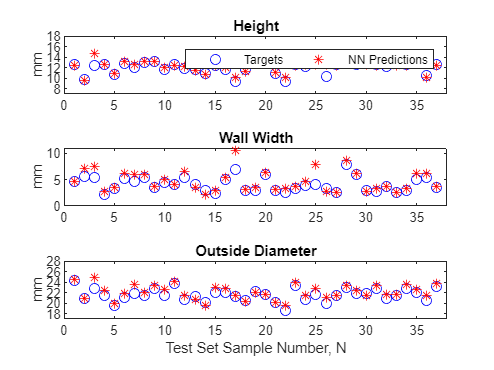

plot(ax3,1:k, testtargets(:,3),'b o', 1:k, y1test(3,:), 'r *')
title(ax3,'Outside Diameter');
ylabel(ax3,'mm');
xlabel(ax3,'Test Set Sample Number, N');
xlim([0 38]);
ylim([17 28]); 


% RMSE of Test Set
test_error = testtargets-y1test';
test_sq_error = (test_error) .^2;
test_sum_sq_error_h = sum(test_sq_error(1,:));
test_sum_sq_error_ww = sum(test_sq_error(2,:));
test_sum_sq_error_od = sum(test_sq_error(3,:));

test_RMSE_h = sqrt(test_sum_sq_error_h/k)

test_RMSE_h = 0.0420

test_RMSE_ww = sqrt(test_sum_sq_error_ww/k)

test_RMSE_ww = 0.2403

test_RMSE_od = sqrt(test_sum_sq_error_od/k)

test_RMSE_od = 0.6078


average_RMSE = (test_RMSE_h + test_RMSE_ww + test_RMSE_od)/3

average_RMSE = 0.2967